clear all;
close all;

%preset = 'example_case';
preset = 'emma_mk1';

switch preset
    case 'example_case'
        drsstc.Lp = 20e-6;
        drsstc.Vbus = 680;
        drsstc.t_d = 2e-6;  % Delay before current stops ringing up after OCD trip
        epsil = 0.01;
        f_prf = 200;    % Hz
        ocd_lim = 800;  % A
        prf_on_time = 250e-6;
        phase_err_rad = 0; % rad
        R_eq = 0.20; % Ohm
    case 'emma_mk1'
        drsstc.Lp = 8e-6;
        drsstc.Vbus = 340;
        drsstc.t_d = 0; % Delay before current stops ringing up after OCD trip
        epsil = 0.01;   % 1 % of I_ocd
        f_prf = 200;    % Hz
        DC_prf = 4;     % %
        ocd_lim = 300;  % A
        phase_err_rad = 0; % rad
        R_eq = 0.0748; % Ohm
        prf_on_time = (DC_prf/100)*(1/f_prf); % sec
    otherwise
        error("Not supported.");
end


## Print RMS Approximation Results

I_mmc_rms = approx_mmc_rms_current(f_prf, prf_on_time, ocd_lim, phase_err_rad, R_eq, epsil, drsstc);

fprintf("Inverter Bus voltage: %0.0f V", drsstc.Vbus );

Inverter Bus voltage: 340 V

fprintf("Primary coil inductance: %0.2f uH", drsstc.Lp*1e6 );

Primary coil inductance: 8.00 uH

fprintf("PRF Frequency: %0.0f Hz", f_prf);

PRF Frequency: 200 Hz

fprintf("PRF on-time: %0.2f usec", prf_on_time*1e6);

PRF on-time: 200.00 usec

fprintf("MMC RMS Current: %0.4f A (rms)", I_mmc_rms);

MMC RMS Current: 31.5553 A (rms)

## Plot Approximation Performance

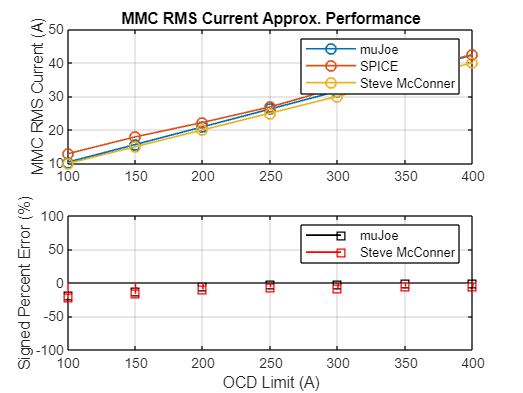

ocd_sweep = [400 350 300 250 200 150 100];
approx_emma_mk1 = zeros(size(ocd_sweep));
sim_emma_mk1 = [42.485 37.124 32.577 26.849 22.224 17.927 12.902];

% Run mujoe approximation
for idx = 1:numel(ocd_sweep)
    ocd = ocd_sweep(idx);
    approx_emma_mk1(idx) = approx_mmc_rms_current(f_prf, prf_on_time, ocd, phase_err_rad, R_eq, epsil, drsstc);
end

% Run steve ward approximation
approx_steve_ward = 0.5 * ocd_sweep * sqrt(prf_on_time * f_prf);

% Compute signed percent error between sim and approximation
spe_mujoe = ((approx_emma_mk1 - sim_emma_mk1) ./ sim_emma_mk1)*100;
spe_steve = ((approx_steve_ward - sim_emma_mk1) ./ sim_emma_mk1)*100;

% Compute MSPE
mspe_mujoe = mean(spe_mujoe);
mspe_steve = mean(spe_steve);

line_width = 1.0;

figure()
subplot(2,1,1);
plot(ocd_sweep,approx_emma_mk1,'-o', 'LineWidth', line_width);
hold on;
plot(ocd_sweep,sim_emma_mk1,'-o','LineWidth',line_width);
hold on;
plot(ocd_sweep, approx_steve_ward,'-o','LineWidth',line_width);
ylabel("MMC RMS Current (A)")
%title(sprintf("Approx. Performance preset: %s",preset));
title("MMC RMS Current Approx. Performance");
legend("muJoe", "SPICE","Steve McConner");
grid on;

subplot(2,1,2);
stem(ocd_sweep,spe_mujoe,'ks','LineWidth',line_width);
hold on;
stem(ocd_sweep,spe_steve,'rs','LineWidth',line_width);
legend('muJoe','Steve McConner');
ylabel('Signed Percent Error (%)');
xlabel("OCD Limit (A)");
grid on;
ylim([-100 100])